## Exercise 2.1

clear;

% p = [x; y; z]; % position of the CoG of the UAV
p = [0; 0; 0];

% p_dot = [x_dot; y_dot; z_dot]; % velocity of the CoG of the UAV
p_dot = [0; 0; 0];

% th = [phi; theta; psi]; % angular position of the body-fixed frame
th = [0; 0; 0];

% th_dot = [phi_dot; theta_dot; psi_dot]; % angular velocity of the body-fixed frame
th_dot = [0; 0; 0];

m = 0.5; % drone mass in the center of gravity of the drone
L = 0.225; % length of each arm of the quadrotor frame
k = 0.01; % overall aerodynamic coefficient necessary to compute the lift of the propellers
b = 0.001; % overall aerodynamic coefficient necessary to compute the drag torque of the propellers
Dx = 0.01; Dy = Dx; Dz = Dx; % drag on the principal axis
Ixx = 3*10^-6; Iyy = Ixx; Izz = 1*10^-5; % moment of inertia on the principal axis
g = [0; 0; -9.81]; % gravitational acceleration

rho = [500; 0; 500; 0]; % angular velocity of the four propellers

%%% Define the rotation matrix representing the orientation 
%%% of the body-fixed frame w.r.t. the inertial frame. (Roll-Pitch-Yaw angles)

% Rotation matrix around the x-axis by angle phi
Rx = [1 0 0; 
    0 cos(-th(1)) sin(-th(1)); 
    0 -sin(-th(1)) cos(-th(1))];

% Rotation matrix around the y-axis by angle theta
Ry = [cos(-th(2)) 0 -sin(-th(2)); 
    0 1 0; 
    sin(-th(2)) 0 cos(-th(2))];

% Rotation matrix around the z-axis by angle psi
Rz = [cos(-th(3)) sin(-th(3)) 0; 
    -sin(-th(3)) cos(-th(3)) 0; 
    0 0 1];

% Rotation matrix
R = Rz * Ry * Rx;

%%% Define the relation between the angular velocity 
%%% and the rotational velocity of the body-fixed frame

% Transformation matrix that converts rotational velocity 
% to angular velocity
Dt = [1 0 -sin(th(2)); 
    0 cos(th(1)) cos(th(2))*sin(th(1)); 
    0 -sin(th(1)) cos(th(2))*cos(th(1))];

% Angular velocity matrix
w = Dt * th_dot;

%%% Write the linear and angular dynamic equation of the drone in compact form, 
%%% and clearly show each component of the equation explicitly

%% Drag on the UAV moving in the air
D = diag([Dx, Dy, Dz]);

%% Moment of inertia of the UAV
I = diag([Ixx, Iyy, Izz]);

%% Forces
% Propeller total thrust
Fb = k * [0; 0; sum(rho.^2)];

% Viscous damping
Fd = -D * [p_dot(1); p_dot(2); p_dot(3)];

Total body torque


$$\tau_B=\left[\begin{array}{c}
L k\left(\omega_1^2-\omega_3^2\right) \\
L k\left(\omega_2^2-\omega_4^2\right) \\
b\left(\omega_1^2-\omega_2^2+\omega_3^2-\omega_4^2\right)
\end{array}\right]$$


taub = [L * k * (rho(1)^2 - rho(3)^2);
    L * k * (rho(2)^2 - rho(4)^2);
    b * (rho(1)^2 - rho(2)^2 + rho(3)^2 - rho(4)^2)];

We recall that the linear dynamics are:


$$\mathbf{m} \ddot{\mathbf{x}}=\left[\begin{array}{c}
0 \\
0 \\
-m g
\end{array}\right]+R F_B+F_D$$


and the rotational dynamics are given as


$$\dot{\omega}=\left[\begin{array}{c}
\dot{\omega}_x \\
\dot{\omega}_y \\
\dot{\omega}_z
\end{array}\right]=I^{-1}\left(\tau_B-\omega \times(I \omega)\right)$$


Given this, we build the model using simulink:

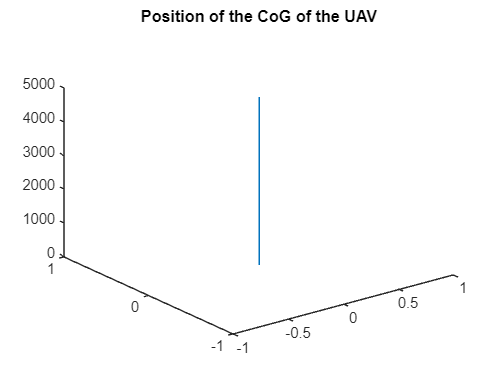

SimData = sim('UAV_model.slx', 1);

figure(1);
plot3(SimData.p_out.signals.values(:,1), SimData.p_out.signals.values(:,2), SimData.p_out.signals.values(:,3));
title('Position of the CoG of the UAV');

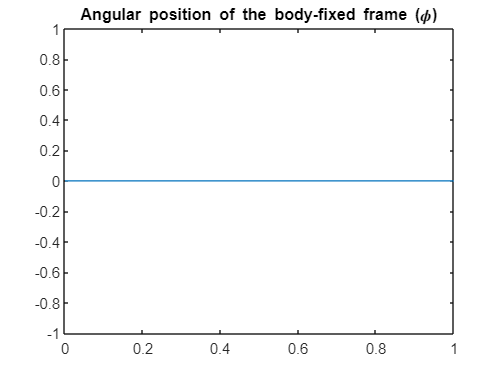


figure(2);
plot(SimData.theta_out.time, SimData.theta_out.signals.values(:,1));
title('Angular position of the body-fixed frame (\phi)');

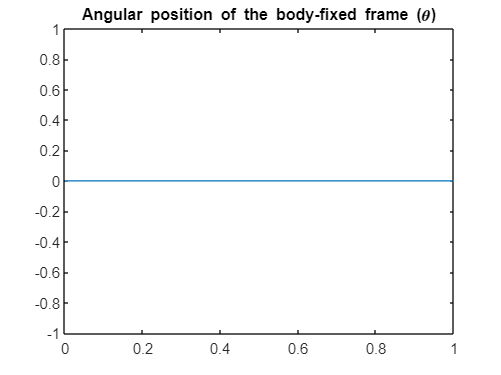


figure(3);
plot(SimData.theta_out.time, SimData.theta_out.signals.values(:,2));
title('Angular position of the body-fixed frame (\theta)');

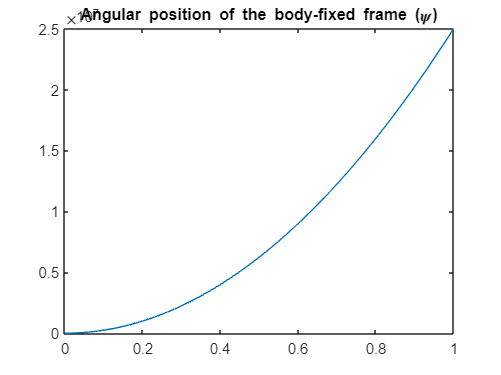


figure(4);
plot(SimData.theta_out.time, SimData.theta_out.signals.values(:,3));
title('Angular position of the body-fixed frame (\psi)');